# Kernel functions for dimensionality reduction 

## Load data

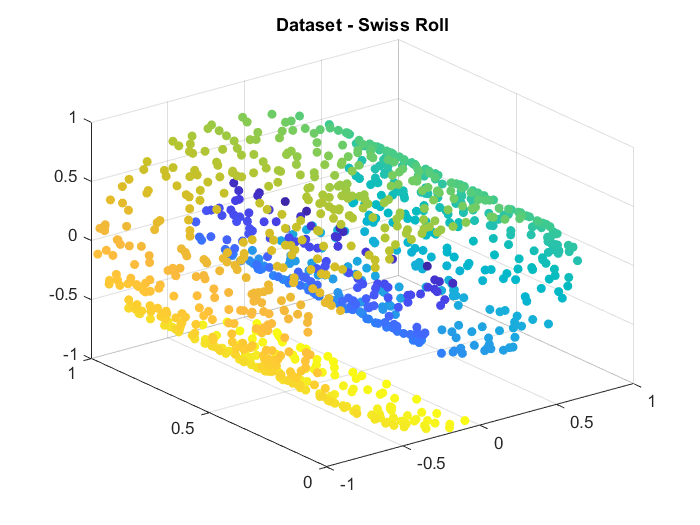

data_opt ="a"   ;
norm_opt =  true;
[X,L,db] = datasets_DR(data_opt,1,norm_opt);
[N,~]    = size(X);
title(['Dataset - ',db])

## Kernel-based DR

### Kernel function

ker_type   = "poly";

Guassian kernel: $k\left(x_i ,x_j \right)=e^{-||x_i -x_j ||^2 /2\sigma {\;}^2 }$

Polynomial kernel: $k\left(x_i ,x_j \right)={\left(1+x_i^{\top \;} x_j \right)}^d$

Linear kernel: $k\left(x_i ,x_j \right)=x_i^{\top \;} x_j$

normalized = true;
step_ker = 1;
lim =20;
par        = 19.01;
figure
subplot(221)
switch ker_type
    case 'gaussian'
        gaussian_kernel_disp(par,lim)
    case 'poly'
       fplot(@(x) (x).^round(par),[-10 10],'Linewidth',2)
    case 'linear'
        fplot(@(x) (x),[-10 10],'Linewidth',2)
end
title({'Kernel function: ',ker_type})

### Kernel matrix

K          = kernelmatrix(X,ker_type,par,normalized);

### Kernel PCA

d  = 2;    
Y  = kernel_PCA(K,d);
subplot(222)
try
    s = scatter3(Y(:,1),Y(:,2),Y(:,3),30,L,'o','filled');
catch
    s = scatter(Y(:,1),Y(:,2),30,L,'o','filled');
end
title({'Reduced data using KPCA with ',ker_type + ' kernel'})

## Structure perservation quality

Ycell{1,1} = Y;
Ycell{2,1} = 'r^';
switch ker_type
    case 'gaussian'
        Ycell{3,1} = strcat('Gauss.(','$\sigma = $'...
            ,num2str(par),')');
    case 'poly'
        Ycell{3,1} = strcat('Poly.(','n = '...
            ,num2str(par),')');
end
subplot(212)
knn = round(N/100);
nx_scores([-N,knn,0],'r',X,Ycell);

Poly.(n =19.01): av.rank= 	1.0 	0.00 stars


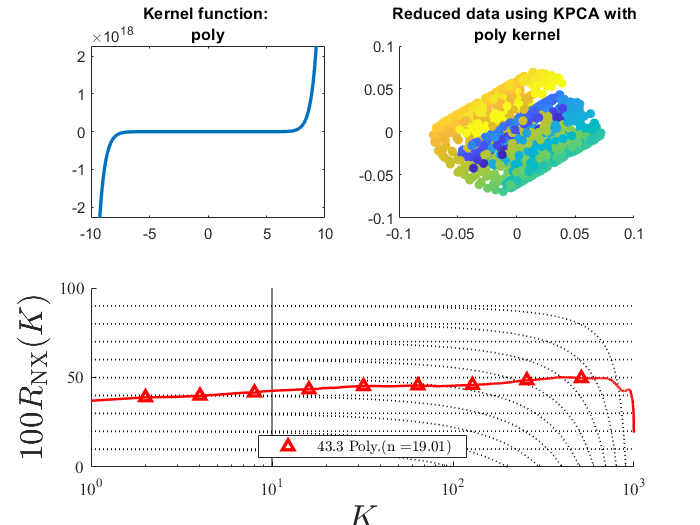

axis([0 N 0 100])

## Data classification

prwarning off
prwaitbar off
% Xds = prdataset(X,round(L));
% [C,D] = gendat(Xds,0.3);
%               % Compute classifiers
% w1 = ldc(C);        % linear
% w2 = qdc(C);        % quadratic
% w3 = parzenc(C);    % Parzen
% w4 = dtc(C);        % decision tree
%               % Compute and display errors
%               % Store classifiers in a cell
% W = {w1,w2,w3,w4};
%               % Plot errors
% disp('**********************************')
% disp('Classfication accuracy for X')
% disp(D*W*testc);    
% disp('**********************************')


Yds = prdataset(Y,round(L));
[C,D] = gendat(Yds,0.3);
              % Compute classifiers
w1 = ldc(C);        % linear
w2 = qdc(C);        % quadratic
w3 = parzenc(C);    % Parzen
w4 = dtc(C);        % decision tree
              % Compute and display errors
              % Store classifiers in a cell
W = {w3};
              % Plot errors
disp('**********************************')

**********************************


disp('Classfication accuracy for Y')

Classfication accuracy for Y


disp(1-D*W*testc);    

    0.6427



disp('**********************************')

**********************************


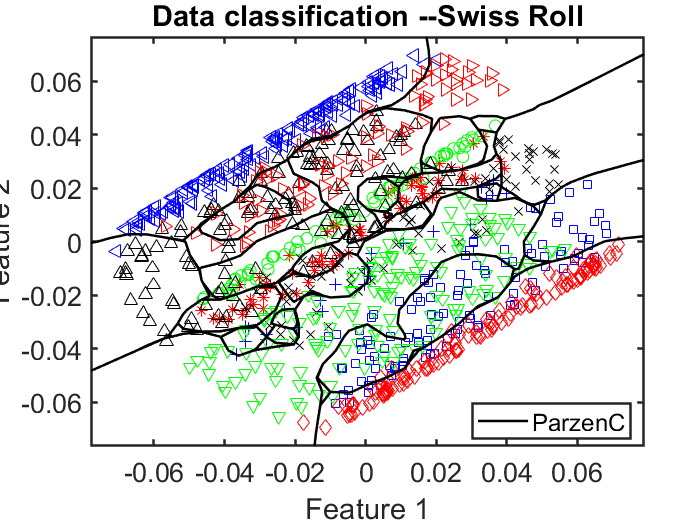

              % Plot the data and classifiers
              % Make a scatter-plot
figure
clf
if d == 2
    scatterd(Yds);            
              % Plot classifiers
    plotc(W);
    title(strcat('Data classification -- ',db))
end